# Anova Stat Inference

***presented by :Darshana Subhash***

An **ANOVA** test is a way to find out if survey or experiment results are [significant](https://www.statisticshowto.com/what-is-statistical-significance/). In other words, they help to figure out if one needs to [reject the null hypothesis](https://www.statisticshowto.com/probability-and-statistics/hypothesis-testing/support-or-reject-null-hypothesis/) or accept the [alternate hypothesis](https://www.statisticshowto.com/what-is-an-alternate-hypothesis/).

- **One-way** or **two-way** refers to the number of [independent variables](https://www.statisticshowto.com/independent-variable-definition/) (IVs) in Analysis of Variance test.

## 
$$I$$


**a) Derive pdf of chi-square distribution**

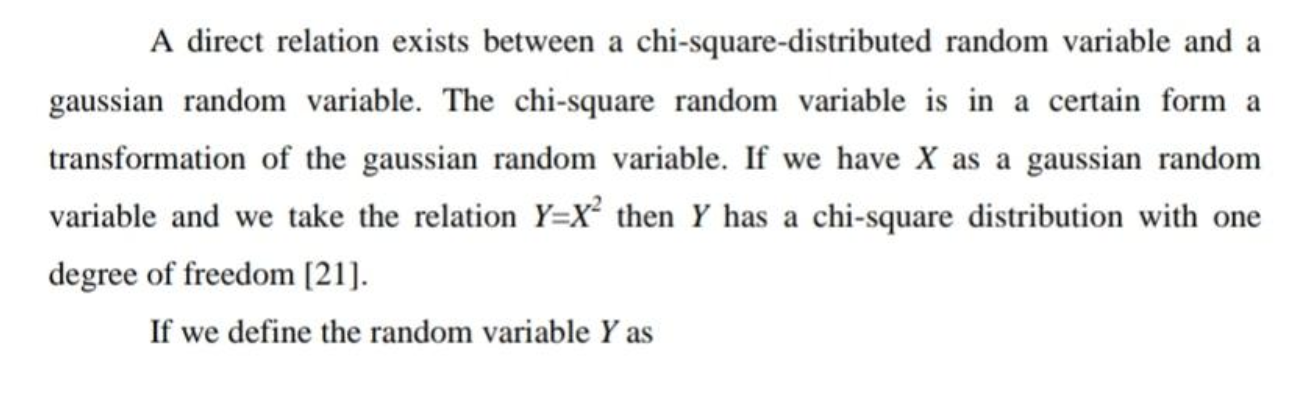

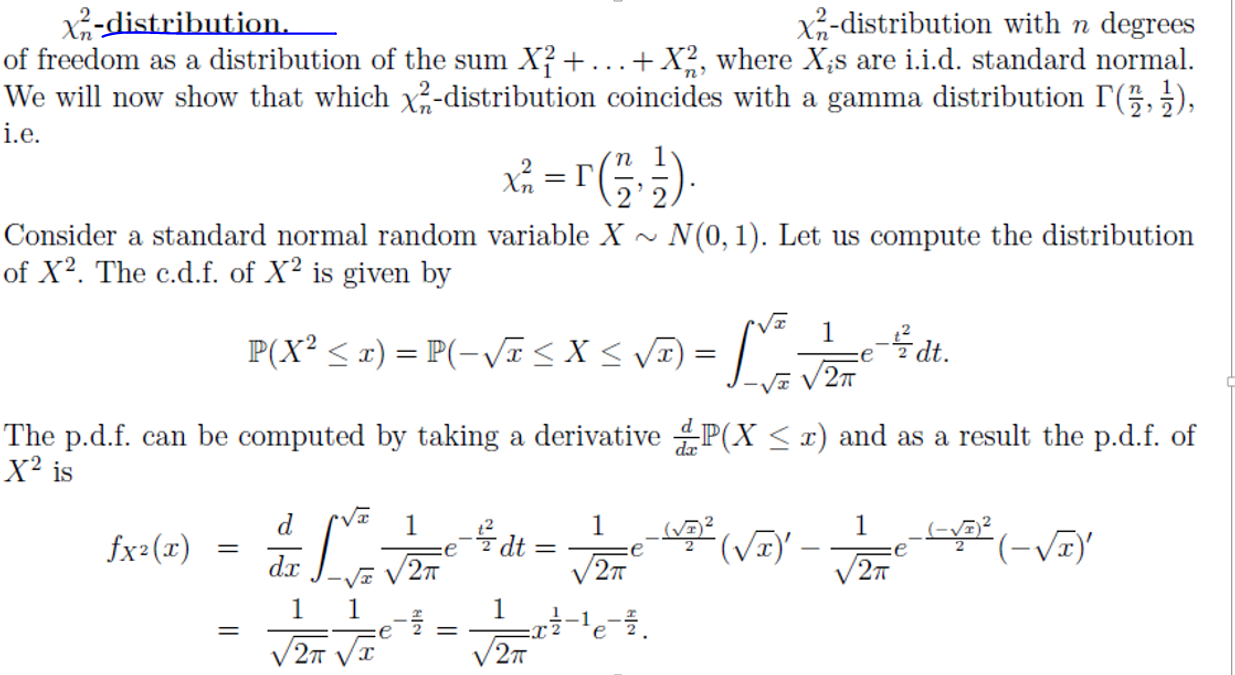

#### **b) How do you plot the pdf in matlab**

x = 0:0.2:15;
x

x =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000    5.2000    5.4000    5.6000    5.8000    6.0000    6.2000    6.4000    6.6000    6.8000    7.0000    7.2000    7.4000    7.6000    7.8000    8.0000    8.2000    8.4000    8.6000    8.8000    9.0000    9.2000    9.4000    9.6000    9.8000


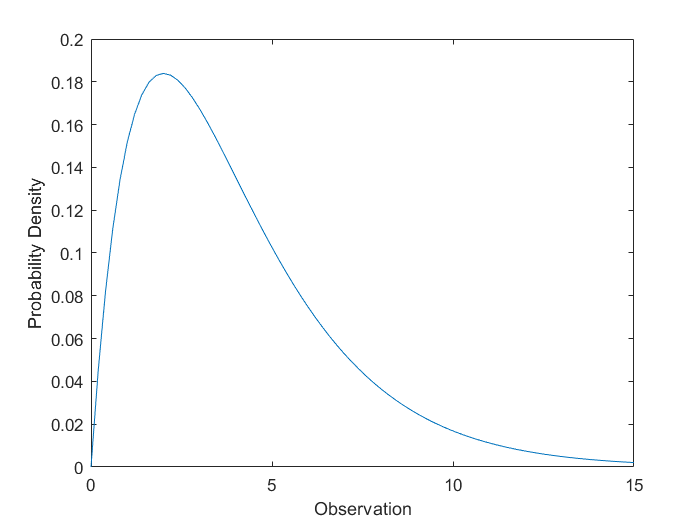

y = chi2pdf(x,4); %here 4 is the degree of freedom
figure;
plot(x,y)
xlabel('Observation')
ylabel('Probability Density')

**c) How to get different percentile of ****F-distribution in ****matlab**

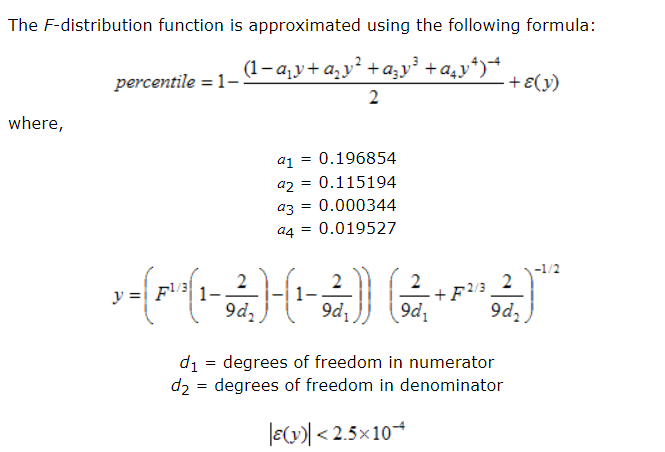

clc; clear 

% Asks the user for the relevant input
f = 0.8457

f = 0.8457

d1 = 3

d1 = 3

d2 = 2

d2 = 2


x = 1;
% Computes using inverse for small F-values
if f < 1
    s = d2;
    t = d1;
    z = 1/f;
else
    s = d1;
    t = d2;
    z = f;
end
j = 2/(9*s);
k = 2/(9*t); 

% Uses approximation formulas
y = abs((1 - k)*z^(1/3) - 1 + j)/sqrt(k*z^(2/3) + j);
if t < 4
    y = y*(1 + 0.08*y^4/t^3);
end 

a1 = 0.196854;
a2 = 0.115194;
a3 = 0.000344;
a4 = 0.019527;
x = 0.5/(1 + y*(a1 + y*(a2 + y*(a3 + y*a4))))^4;
x = floor(x*10000 + 0.5)/10000; 

% Adjusts if inverse was computed
if f < 1
    x = 1 - x;
end 

% Displays results
str1 = ['Percentile = ' num2str(1-x)];
str2 = ['Tail end value = ' num2str(x)];
disp(str1)

Percentile = 0.4189


disp(str2)

Tail end value = 0.5811


#### **d) Show an example of the use of **

       **chi-square distribution in testing of**

       **hypothesis.**

Let A,B,C,D be the choices for each questions.Probability of choosing any one choice is 25%

H_0: Equal Distribution of correct choices.

H_1: Unequal Distribution.

Assuming Null Hypothesis is true,

%choice=[A B C D]
Expected=[25 25 25 25]

Experted =     25    25    25    25


Actual=[20 20 25 35]

Actual =     20    20    25    35


alpha=0.05

alpha = 0.0500

ChisSquare = sum((Actual-Expected).^2 ./ Expected)

ChisSquare = 6

p=1-chi2cdf(ChisSquare,3)

p = 0.1116


[h,p,stats] = chi2gof([1 2 3 4],'freq',Actual,'Expected',Expected,'ctrs',[1 2 3 4],'nparams',3)

h = 0

p = NaN

stats = struct with fields:
    chi2stat: 6
          df: 0
       edges: [0.5000 1.5000 2.5000 3.5000 4.5000]
           O: [20 20 25 35]
           E: [25 25 25 25]


%Here, probability of getting chi-squared value greater than or equal to
%six is going to be greater than 10% 
%And so far our probability assuming the Null Hypothesis is greater than
% 10%.This is greater than significance level.
%P(Chi-square>=6)>10%
%Hence, we will fail to reject the H_0

**e) Find and**  **Discuss other uses of ****chi-square distribution .**

- [Chi-square test](https://en.wikipedia.org/wiki/Pearson%27s_chi-square_test) of goodness of fit of observed data to hypothetical distributions: The primary reason for which the chi-square distribution is extensively used in hypothesis testing is its relationship to the normal distribution. The simplest chi-square distribution is the square of a standard normal distribution. So wherever a normal distribution could be used for a hypothesis test, a chi-square distribution could be used.

- It is also a component of the definition of the [t-distribution](https://en.wikipedia.org/wiki/Student%27s_t-distribution) and the [F-distribution](https://en.wikipedia.org/wiki/F-distribution) used in t-tests, analysis of variance, and regression analysis.

- [Likelihood-ratio test](https://en.wikipedia.org/wiki/Likelihood-ratio_test) for nested models:In [statistics](https://en.wikipedia.org/wiki/Statistics), the **likelihood-ratio test** assesses the [goodness of fit](https://en.wikipedia.org/wiki/Goodness_of_fit) of two competing [statistical models](https://en.wikipedia.org/wiki/Statistical_model) based on the ratio of their [likelihoods](https://en.wikipedia.org/wiki/Likelihood_function).

**2**

**a).Derive pdf of F distribution**

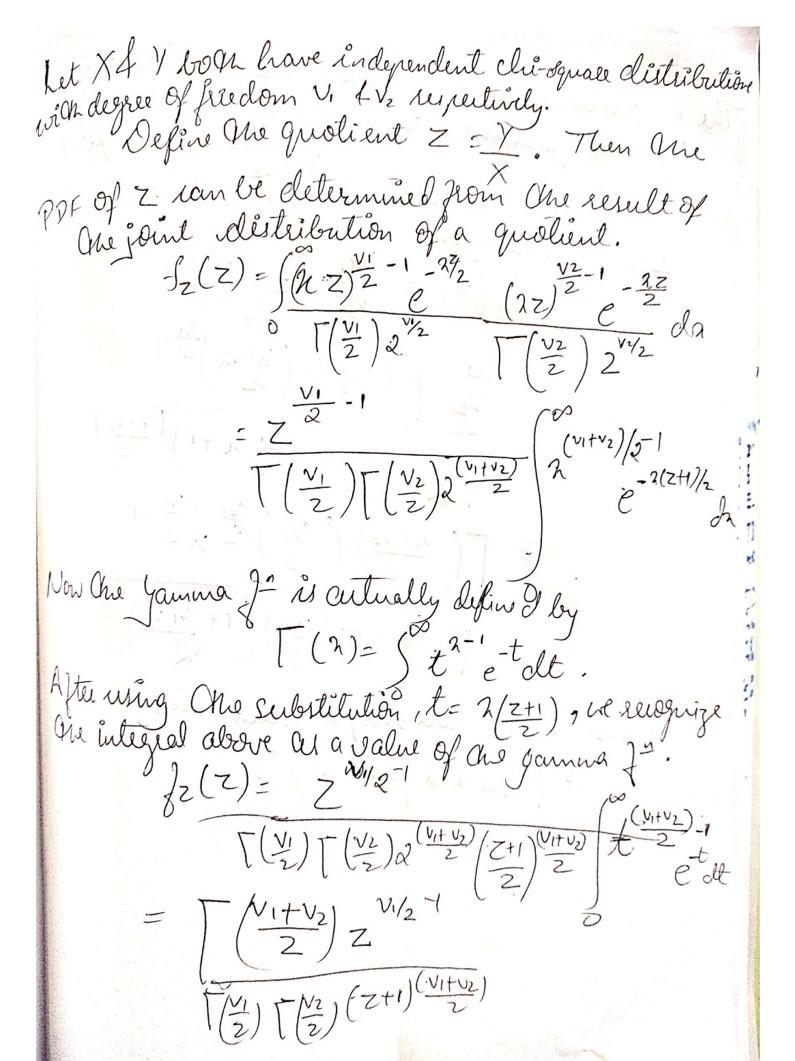

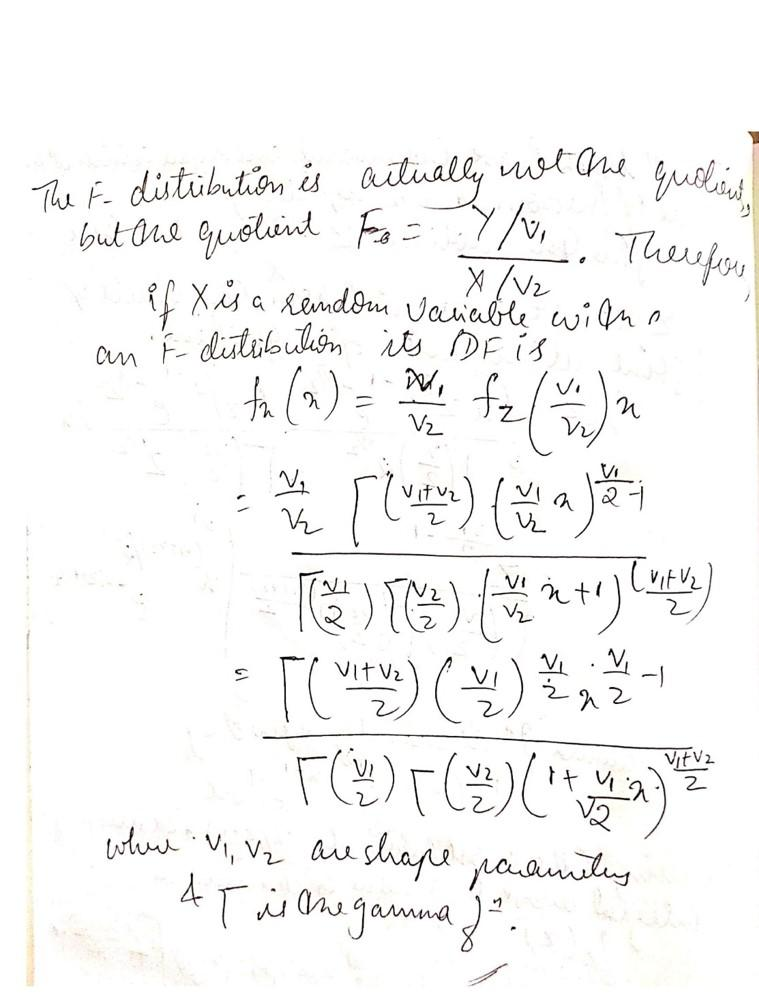

**b)** **How do you plot the pdf of f-ditribution in ****matlab**

x = 0:0.01:10

x =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


% F distribution with 5 numerator degrees of freedom and 3 denominator degrees of freedom.
y = fpdf(x,5,3)

y =          0    0.0171    0.0453    0.0781    0.1129    0.1483    0.1833    0.2175    0.2505    0.2819    0.3117    0.3398    0.3661    0.3907    0.4135    0.4346    0.4541    0.4720    0.4883    0.5033    0.5169    0.5292    0.5402    0.5501    0.5590    0.5668    0.5737    0.5796    0.5848    0.5892    0.5928    0.5958    0.5981    0.5998    0.6010    0.6017    0.6020    0.6017    0.6011    0.6001    0.5988    0.5972    0.5952    0.5930    0.5905    0.5878    0.5849    0.5818    0.5786    0.5752


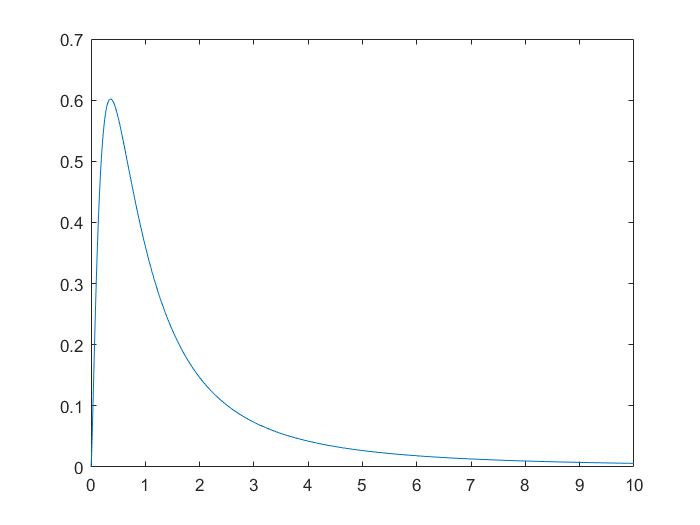

figure
plot(x,y)

**d) Why F test in ****Anova**** is one tailed**

An *F*-test is used to test if the variances of two populations are equal. This test can be a two-tailed test or a one-tailed test. The two-tailed version tests against the alternative that the variances are not equal. The one-tailed version only tests in one direction, that is the variance from the first population is either greater than or less than (but not both) the second population variance. The choice is determined by the problem. 

For example, if we are testing a new process, we may only be interested in knowing if the new process is less variable than the old process.

#### **IV. Give a method to generate 5 population data such that **

#### ** 4 means are statistically equal and one mean is different from the**

#### **Rest. In each population take 10 data. **

#### **Apply oneway ANOVA and show that most of the time  null hypothesis**

#### **is rejected.**

**Sol:**The **null hypothesis** for an **ANOVA is** that there **is no** significant difference among the groups. If the **null hypothesis is rejected**, one concludes that the means of all the groups are **not** equal.

ANOVA rejects the null hypothesis that all group means are equal.

Using the multiple comparisons to determine which group means are different from others. In this example, `anova1` rejects the null hypothesis that the mean of data from all 5 population groups are equal to each other, i.e., *H*0:*μ*1=*μ*2=*μ*3=*μ*4=*μ5.*

Graphical assurance that the means are different by looking at the box plots.

#### **Write a Matlab code to do every thing**

**Step1:8**

clear all;clc;
clf;
rng(12345);
sigma=3;
mu1=160;
mu2=150;
m=10;  % number of data in each column
n=4;  % number columns (no of population)
for i=1:10
A=normrnd(mu1,sigma,m,n);
[m,n]=size(A);
B=normrnd(mu2,sigma,m,1);
end
C=[A B]

C =   152.4643  160.0348  162.3452  159.9328  147.5889
  161.2525  161.6983  158.8613  163.9731  150.0472
  160.6205  164.3541  160.8715  160.7845  150.3422
  154.6573  156.5117  157.3612  161.0915  146.9326
  160.7071  159.2705  162.0211  161.9667  148.0689
  159.4307  161.3213  159.5143  164.2879  147.0921
  157.9835  163.7618  165.0271  161.8561  149.3168
  168.9721  157.1811  157.7458  162.0225  151.2025
  156.0101  160.1246  161.4048  154.4458  148.5179
  157.3899  160.0037  162.1639  160.9601  147.7095


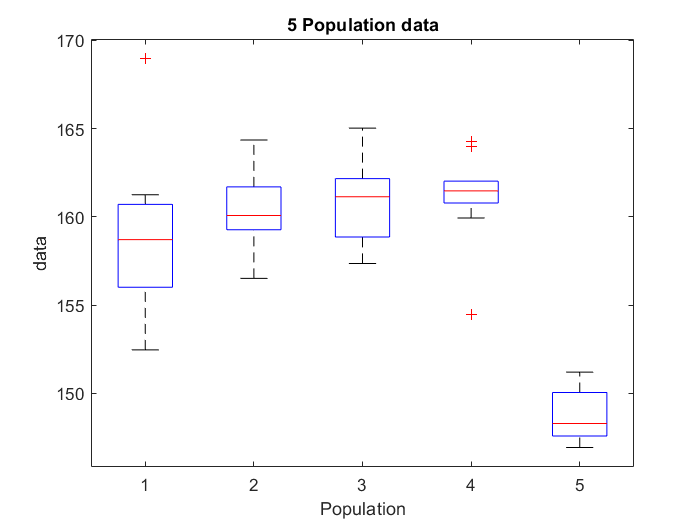

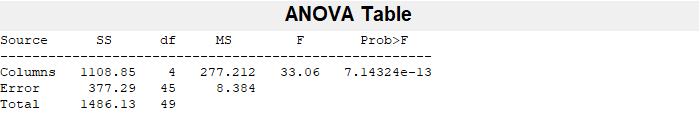

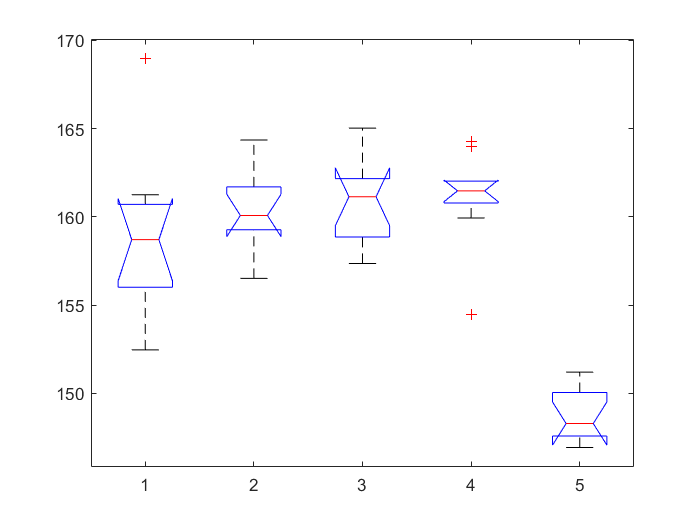

boxplot(C)
title('5 Population data')
xlabel('Population')
ylabel('data')
[p,tbl,stats] = anova1(C);

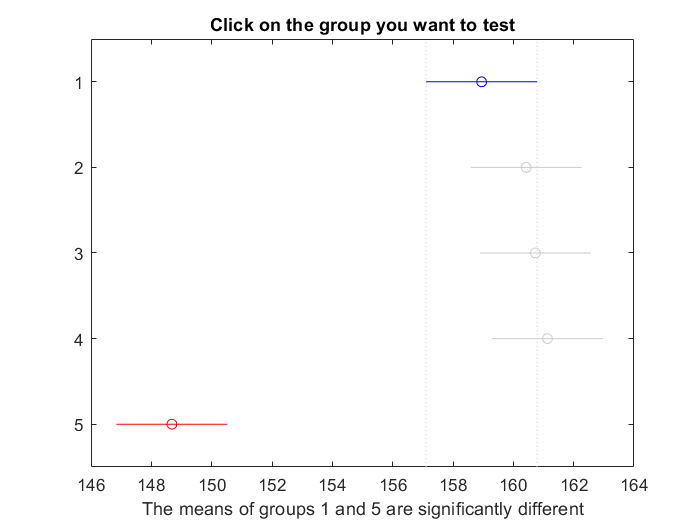

ans =     1.0000    2.0000   -5.1568   -1.4774    2.2021    0.7840
    1.0000    3.0000   -5.4623   -1.7828    1.8966    0.6453
    1.0000    4.0000   -5.8628   -2.1833    1.4962    0.4526
    1.0000    5.0000    6.5875   10.2669   13.9464    0.0000
    2.0000    3.0000   -3.9849   -0.3054    3.3740    0.9993
    2.0000    4.0000   -4.3854   -0.7059    2.9735    0.9820
    2.0000    5.0000    8.0649   11.7443   15.4238    0.0000
    3.0000    4.0000   -4.0799   -0.4005    3.2790    0.9979
    3.0000    5.0000    8.3703   12.0498   15.7292    0.0000
    4.0000    5.0000    8.7708   12.4502   16.1297    0.0000


multcompare(stats)


p<0.05

ans = logical
   1



%OR

[m,n]=size(C);  % n= number of population groups, m=#of data
ytbars=sum(C)/m; % n group averages
ybar=sum(ytbars)/n; % grand mean
ytbarsmatrix=repmat(ytbars,m,1);
ybarmatrix=ybar*ones(m,n);
SSTotal=sumsqr(C-ybarmatrix);
SSbetween=sumsqr(ytbarsmatrix-ybarmatrix);
SSError=sumsqr(C-ytbarsmatrix);
dfbetween=n-1;
dfError=m*n-n;
MSbetween=SSbetween/dfbetween;
MSError=SSError/dfError;
Fval_comp=MSbetween/MSError

Fval_comp = 33.0640

p = fcdf(Fval_comp,dfbetween,dfError) % cumulative f distribution 

p = 1.0000

pbar=1-p;   % right tail area beyond Fval_computed
fdist_cutoff=finv(0.95,dfbetween,dfError)   

fdist_cutoff = 2.5787

#### **V. **Give a method to generate 2 way ANOVA data with A at 3 levels and B

#### at 4 levels. For  each combination take 10 data. 

#### Data should be such that 2 way ANOVA almost always accept 

#### the null hypothesis 

#### (means of all levels in A are equal, means of all levels in B are equal 

#### and there is no interaction between A and B)

%Synthetic data Visualization
clear all;clc;
clf;
rng default;
A=3;
B=4;
n=10;
X=cell(A,B,1);
for j=1:A
    for k=1:B
        X(j,k)={normrnd(160,0.05,1,n)};
    end
    
end
X

X = 3×4 cell array
    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}
    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}
    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}



%Synthetic data Creation

clear all;clc;
clf;
rng default;
A=3;
B=4;
n=10;
for j=1:A
    for k=1:B
        X(:,j,k)=normrnd(160,1,1,n);
        cellavg(j,k)=mean(X(:,j,k));
        SSerr(j,k)=sum(sum(((X(:,j,k)-cellavg(j,k)).^2),2));
    end
    
end
Y=reshape(X(:),n*A,B)

Y =   160.5377  158.6501  160.6715  160.8884
  161.8339  163.0349  158.7925  158.8529
  157.7412  160.7254  160.7172  158.9311
  160.8622  159.9369  161.6302  159.1905
  160.3188  160.7147  160.4889  157.0557
  158.6923  159.7950  161.0347  161.4384
  159.5664  159.8759  160.7269  160.3252
  160.3426  161.4897  159.6966  159.2451
  163.5784  161.4090  160.2939  161.3703
  162.7694  161.4172  159.2127  158.2885


cellavg

cellavg =   160.6243  160.7049  160.3265  159.5586
  160.2059  159.8905  160.1282  159.7354
  160.3030  159.7536  160.1958  159.6460


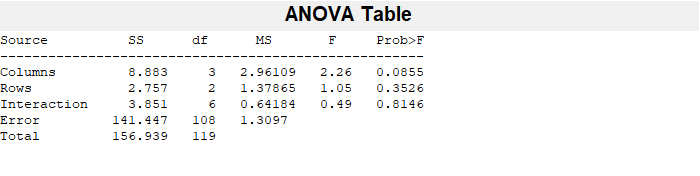

p =     0.0855    0.3526    0.8146


stats = struct with fields:
      source: 'anova2'
     sigmasq: 1.3097
    colmeans: [160.3777 160.1163 160.2168 159.6467]
        coln: 30
    rowmeans: [160.3036 159.9900 159.9746]
        rown: 40
       inter: 1
        pval: 0.8146
          df: 108



%anova two way using inbuilt function
[p,~,stats]=anova2(Y,n)

#### In a 3 way ANOVA with factors A , B and C

#### A is having 4 levels

#### B is having 3 levels

#### C is having 3 levels.

#### 10 experiment is done for each factor level combination.

#### (4x3x3x10 experimental data).

#### Assume all interactions are absent.

#### What is  

#### 1)DF of A

#### 2)DF of B

#### 3)DF of C

#### 4)DF of Error

#### 5)Total DF

#### 6)For 5% significant level , what are the 3 critical values of F distribution 

In 3 way Anova with factors A,B,C:

**1) **A is having 4 levels  => **DF of A is **4-1=3

**2)** B is having 3 levels  => **DF of B is ** 3-1=2

**3)** C is having 3 levels  => **DF of C is **3-1=2

Given that : 10 experiment is done for each factor level combination

**DF of AB  **= (DF of A)*(DF of B) = 3*2=6

**DF of AC **= (DF of A)*(DF of C) = 3*2=6

**DF of BC **= (DF of B)*(DF of C) = 2*2=4

**DF of ABC **=  (DF of A)*(DF of B)*(DF of C) =3* 2*2=12

**4)** **DF of Error** = **Total DF - (DF of A+DF of B+DF of C +DF of AB +DF of BC +DF of AC)**

                    =  359-(3+2+2+6+6+4+12)

                    = 324

                      **OR**

**4) DF of Error **= 4*3*3*(10-1)

                   = 324

**5) Total DF :** (4*3*3*10)  -- 1 = 360-1 = 359

**6)For 5% significant level , what are the 3 critical values of F distribution **

**Using F-distribution table**

**F_A **= F(3,324) = 2.6325 

**F_B **=F(2,324) =3.0236

**F_C **=F(2,324) =3.0236

fdist_cutoff=finv(0.95,3,324) 

fdist_cutoff = 2.6325

fdist_cutoff=finv(0.95,2,324) 

fdist_cutoff = 3.0236